# 802.11b SEM (dB scale)

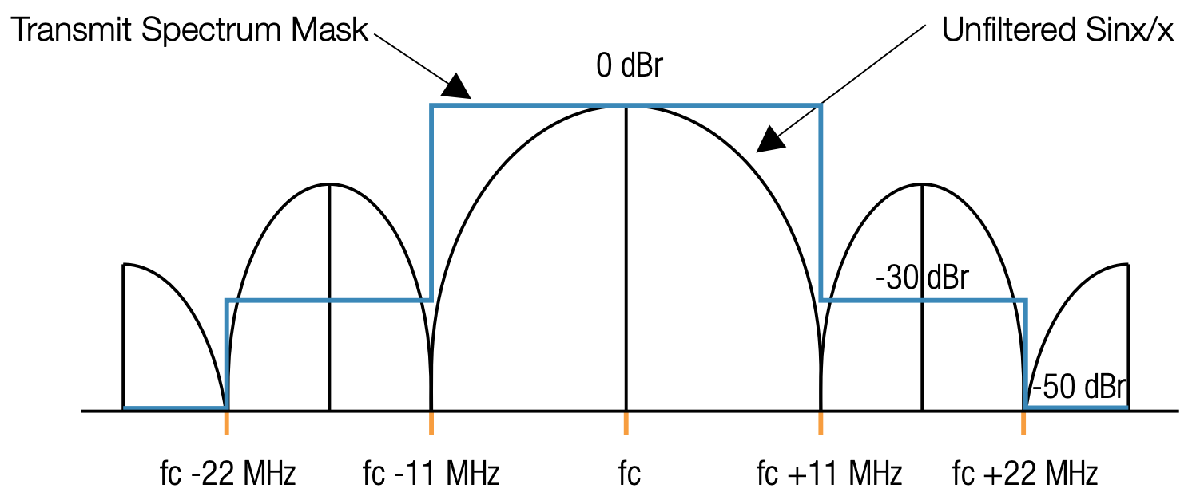

### Normalized frequency $fT_s = \frac{f}{f_s
}\in [-0.5, 0.5]$

### Definition of the 20 Mhz 802.11b SEM function in $f$ (MHz)


$$\mathrm{SEM}(f) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |f| \leq 11\\
-30 & \mbox{if } \quad 11\leq |f| \leq 22\\
-50 & \mbox{if } \quad |f| \geq 22\\
\end{array}\right.$$


### Definition of the 802.11ac SEM in $f, f_s$ (MHz)


$$\mathrm{SEM}(f, f_s) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |f| \leq \frac{11}{f_s}\\
-30 & \mbox{if } \quad \frac{11}{f_s}\leq |f| \leq \frac{22}{f_s}\\
-50 & \mbox{if } \quad |f| \geq \frac{22}{f_s}\\
\end{array}\right.$$


function SEM = SEM_b(fTs, fs, channel_size)
% Keep only the positive part
fTs = fTs((length(fTs)+1)/2 : end);
SEM = zeros(length(fTs), 1);

fs = 2*fs;

if channel_size == 20   % on_ratio = 0.5485
    for idx = 1:length(f)
        if f(idx) < 11/fs
            % freq: 0~11 MHz
            SEM(idx) = 0;
        elseif f(idx) < 22/fs
            % freq: 11~22 MHz
            SEM(idx) = -30;
        else
            % freq: >22 MHz
            SEM(idx) = -50;
        end
    end

% Generate the negative part
SEM = [flipud(SEM); SEM(2:end)];
end